tvals = [1 2 2.5 4];
qvals = [45 90 -45 45];

v1 = 0;
vn = 0;
print_info = true;

[coeffs, v] = cubic_splines_norm(tvals, qvals, v1, vn, true);

We need 3 cubic poly
For each k-th cubic function:
	q_k(tau) = a_k3*tau^3 + a_k2*tau^2 + a_k1*tau + a_k0
	tau € [0, 1]; tau = t-t_k/h_k; h_k = t_k+1 - t_k
First at all we compute the intermediate velocities v2 ... vn-1
To do that we write the following linear system Ax=b where x=[v2 ... vn-1]


$$A = \left(\begin{array}{cc} 2\,t_{3}-2\,t_{1} & t_{2}-t_{1}\\ t_{4}-t_{3} & 2\,t_{4}-2\,t_{2} \end{array}\right)$$

$$b = \left(\begin{array}{c} -\frac{\left(3\,q_{1}-3\,q_{2}\right)\,\left(t_{2}-t_{3}\right)}{t_{1}-t_{2}}-\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{1}-t_{2}\right)}{t_{2}-t_{3}}\\ -\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{3}-t_{4}\right)}{t_{2}-t_{3}}-\frac{\left(3\,q_{3}-3\,q_{4}\right)\,\left(t_{2}-t_{3}\right)}{t_{3}-t_{4}} \end{array}\right)$$

By replacing symbols with numbers we obtain:
 

$$A = \left(\begin{array}{cc} 3 & 1\\ \frac{3}{2} & 4 \end{array}\right)$$

$$b = \left(\begin{array}{c} -\frac{1485}{2}\\ -1125 \end{array}\right)$$

With the result:


$$v = \left(\begin{array}{c} -\frac{1230}{7}\\ -\frac{3015}{14} \end{array}\right)$$

All the velocities at each knots are the following:


v =          0
 -175.7143
 -215.3571
         0


Now we compute coefficients of each cubic function
For each function i-th to compute a2 and a3 we have to solve the following linear system (Ax=b)


$$A\_\_ = \left(\begin{array}{cc} 1 & 1\\ \frac{2}{h_{i}} & \frac{3}{h_{i}} \end{array}\right)$$

$$b\_\_ = \left(\begin{array}{c} q_{j}-q_{i}-h_{i}\,v_{i}\\ v_{j}-v_{i} \end{array}\right)$$

Where j = i+1 and h_i = t_j - t_i
Others coefficients are instead immediately computable:
a0 = q_i
a1 = v_i*h_i

Coefficients of all cubic functions -------------------


coeffs =    45.0000         0  310.7143 -265.7143
   90.0000  -87.8571 -121.6071   74.4643
  -45.0000 -323.0357  916.0714 -503.0357


Symbolic Cubic 1 parameters:
a0 = 45.000000 
a1 = 0.000000 
a2 = 310.714286 
a3 = -265.714286 

Symbolic Cubic 2 parameters:
a0 = 90.000000 
a1 = -87.857143 
a2 = -121.607143 
a3 = 74.464286 

Symbolic Cubic 3 parameters:
a0 = -45.000000 
a1 = -323.035714 
a2 = 916.071429 
a3 = -503.035714 

-------------------------------------------------------

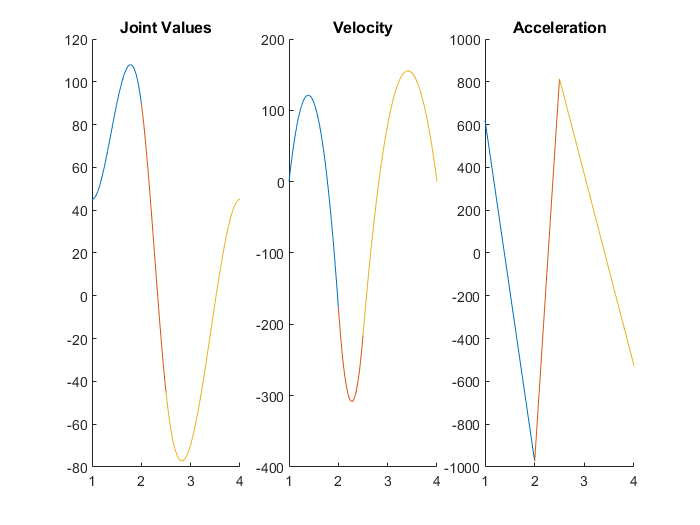

N = 4

clf
spline_plot_norm(tvals, coeffs)

tvals = [1 2 2.5 4];
qvals = [45 90 -45 45];

v1 = 0;
vn = 0;
print_info = true;

[coeffs, v] = cubic_splines_norm(tvals, qvals, v1, vn, true);

We need 3 cubic poly
For each k-th cubic function:
	q_k(tau) = a_k3*tau^3 + a_k2*tau^2 + a_k1*tau + a_k0
	tau € [0, 1]; tau = t-t_k/h_k; h_k = t_k+1 - t_k
First at all we compute the intermediate velocities v2 ... vn-1
To do that we write the following linear system Ax=b where x=[v2 ... vn-1]


$$A = \left(\begin{array}{cc} 2\,t_{3}-2\,t_{1} & t_{2}-t_{1}\\ t_{4}-t_{3} & 2\,t_{4}-2\,t_{2} \end{array}\right)$$

$$b = \left(\begin{array}{c} -\frac{\left(3\,q_{1}-3\,q_{2}\right)\,\left(t_{2}-t_{3}\right)}{t_{1}-t_{2}}-\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{1}-t_{2}\right)}{t_{2}-t_{3}}\\ -\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{3}-t_{4}\right)}{t_{2}-t_{3}}-\frac{\left(3\,q_{3}-3\,q_{4}\right)\,\left(t_{2}-t_{3}\right)}{t_{3}-t_{4}} \end{array}\right)$$

By replacing symbols with numbers we obtain:
 

$$A = \left(\begin{array}{cc} 3 & 1\\ \frac{3}{2} & 4 \end{array}\right)$$

$$b = \left(\begin{array}{c} -\frac{1485}{2}\\ -1125 \end{array}\right)$$

With the result:


$$v = \left(\begin{array}{c} -\frac{1230}{7}\\ -\frac{3015}{14} \end{array}\right)$$

All the velocities at each knots are the following:


v =          0
 -175.7143
 -215.3571
         0


Now we compute coefficients of each cubic function
For each function i-th to compute a2 and a3 we have to solve the following linear system (Ax=b)


$$A\_\_ = \left(\begin{array}{cc} 1 & 1\\ \frac{2}{h_{i}} & \frac{3}{h_{i}} \end{array}\right)$$

$$b\_\_ = \left(\begin{array}{c} q_{j}-q_{i}-h_{i}\,v_{i}\\ v_{j}-v_{i} \end{array}\right)$$

Where j = i+1 and h_i = t_j - t_i
Others coefficients are instead immediately computable:
a0 = q_i
a1 = v_i*h_i

Coefficients of all cubic functions -------------------


coeffs =    45.0000         0  310.7143 -265.7143
   90.0000  -87.8571 -121.6071   74.4643
  -45.0000 -323.0357  916.0714 -503.0357


Symbolic Cubic 1 parameters:
a0 = 45.000000 
a1 = 0.000000 
a2 = 310.714286 
a3 = -265.714286 

Symbolic Cubic 2 parameters:
a0 = 90.000000 
a1 = -87.857143 
a2 = -121.607143 
a3 = 74.464286 

Symbolic Cubic 3 parameters:
a0 = -45.000000 
a1 = -323.035714 
a2 = 916.071429 
a3 = -503.035714 

-------------------------------------------------------

N = 4

clf
spline_plot_norm(tvals, coeffs)

    if length(tvals) ~= length(qvals)
        fprintf("arrays of positions and times must have same size! \n")
    end
    
    % tau = t - t1 --> tau = (t - t1) / h
    normalize = 1;
%    if exist('norm', 'var')
%        normalize = norm;
%    else
%        normalize = 1;
%    end


    %% Calcs
    N = size(tvals, 2);
    t = sym ('t', [1, N], 'real');
    q = sym ('q', [1, N], 'real');
    v = sym ('v', [1, N], 'real');

    v(1) = v1;
    v(N) = vn;

    %build array of time intervals
    %% h(1) = t2 - t1
    %% h(2) = t3 - t2 and so on ...
    h = t(2:N) - t(1:N-1);

    
    if print_info
        fprintf("We need %d cubic poly\n", N-1);
        fprintf("For each k-th cubic function:\n")
        fprintf("\tq_k(tau) = a_k3*tau^3 + a_k2*tau^2 + a_k1*tau + a_k0\n")
        fprintf("\ttau € [0, 1]; tau = t-t_k/h_k; h_k = t_k+1 - t_k\n")
    end

We need 2 cubic poly


For each k-th cubic function:


	q_k(tau) = a_k3*tau^3 + a_k2*tau^2 + a_k1*tau + a_k0


	tau € [0, 1]; tau = t-t_k/h_k; h_k = t_k+1 - t_k


    
    % A is a N-2 x N-2 matrix
    % The same for all joints
    A = sym(zeros([N-2, N-2]));
    for i = 1:N-2
        if i-1 > 0
            A(i-1, i) = h(i-1);
        end
        A(i, i) = 2 * (h(i) + h(i+1));
        if i+1 <= N-2
            A(i+1, i) = h(i+2);
        end
    end

    % b changes for each joint
    % as it depends on q
    b = sym(zeros([N-2, 1]));
    for i = 1:N-2
        b(i) = 3 * (q(i+2) - q(i+1)) * h(i)/h(i+1) + 3 * (q(i+1) - q(i)) * h(i+1)/h(i);
    end
    b = b - [h(2) * v1; zeros([N-4,1]); h(N-2) * vn];

    if print_info
        fprintf("First at all we compute the intermediate velocities v2 ... vn-1\n");
        fprintf("To do that we write the following linear system Ax=b where x=[v2 ... vn-1]\n");
        display(A);
        display(b);
    end

First at all we compute the intermediate velocities v2 ... vn-1


To do that we write the following linear system Ax=b where x=[v2 ... vn-1]


$$A = 2\,t_{3}-2\,t_{1}$$

$$b = \left(\begin{array}{c} -\frac{\left(3\,q_{1}-3\,q_{2}\right)\,\left(t_{2}-t_{3}\right)}{t_{1}-t_{2}}-\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{1}-t_{2}\right)}{t_{2}-t_{3}}\\ -\frac{\left(3\,q_{1}-3\,q_{2}\right)\,\left(t_{2}-t_{3}\right)}{t_{1}-t_{2}}-\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{1}-t_{2}\right)}{t_{2}-t_{3}} \end{array}\right)$$

    


    
    %% Numberical Results
    % Convert everything to numerical values
    A = subs(A, t, tvals);
    b = subs(b, t, tvals);
    b = subs(b, q, qvals);
    h = subs(h, t, tvals);

    v1 = subs(v1, q, qvals);
    v1 = subs(v1, t, tvals);
    vn = subs(vn, q, qvals);
    vn = subs(vn, t, tvals);

    v = inv(A) * b;
    v = v(1)

$$v = \frac{39\,\pi }{280}$$

    if print_info
        fprintf("By replacing symbols with numbers we obtain:\n ");
        display(A);
        display(b);
        fprintf("With the result:\n");
        display(v);
    end

By replacing symbols with numbers we obtain:
 

$$A = 7$$

$$b = \left(\begin{array}{c} \frac{39\,\pi }{40}\\ \frac{39\,\pi }{40} \end{array}\right)$$

With the result:


$$v = \frac{39\,\pi }{280}$$

    
    v = eval([v1; v; vn]);
    
    if print_info
        fprintf("All the velocities at each knots are the following:\n")
        display(v);
    end

All the velocities at each knots are the following:


v =          0
    0.4376
         0



    % compute coefficients
    %{ 
    NOT NORMALIZED
    if print_info
        fprintf("Now we compute coefficients of each cubic function");
        fprintf("For each function to compute a2 and a3 we have to solve the following linear system (Ax=b)")
        syms h_i q_i q_j v_i v_j
        A__ = [h_i^2, h_i^3;
             2*h_i, 3*h_i^2];
        
        b__ = [q_j - q_i - v_i * h_i; 
                            v_j - v_i];
        display(A__);
        display(b__);
        fprintf("Where j = i+1 and h_i = t_j - t_i\n");
        fprintf("Others coefficients are instead immediately computable:");
        fprintf("a0 = q_i\na1 = v_i\n");
    end
    %}
    
    if print_info
        fprintf("Now we compute coefficients of each cubic function\n");
        fprintf("For each function i-th to compute a2 and a3 we have to solve the following linear system (Ax=b)\n")
        syms h_i q_i q_j v_i v_j
        A__ = [1, 1;
             2/h_i, 3/h_i];
        
        b__ = [q_j - q_i - v_i * h_i; 
                            v_j - v_i];
        display(A__);
        display(b__);
        fprintf("Where j = i+1 and h_i = t_j - t_i\n");
        fprintf("Others coefficients are instead immediately computable:\n");
        fprintf("a0 = q_i\na1 = v_i*h_i\n");
    end

Now we compute coefficients of each cubic function


For each function i-th to compute a2 and a3 we have to solve the following linear system (Ax=b)


$$A\_\_ = \left(\begin{array}{cc} 1 & 1\\ \frac{2}{h_{i}} & \frac{3}{h_{i}} \end{array}\right)$$

$$b\_\_ = \left(\begin{array}{c} q_{j}-q_{i}-h_{i}\,v_{i}\\ v_{j}-v_{i} \end{array}\right)$$

Where j = i+1 and h_i = t_j - t_i


Others coefficients are instead immediately computable:


a0 = q_i
a1 = v_i*h_i


        
    coeffs = [];
    for i = 1:N-1
        % fprintf('Numeric Cubic %d parameters:\n', i);
        a0 = qvals(i);
        
        if normalize == 1
            a1 = v(i) * h(i);
            a = inv([1, 1; 2/h(i), 3/h(i)]) * [qvals(i+1) - qvals(i) - v(i) * h(i); v(i+1) - v(i)];
        else
            a1 = v(i);
            a = inv([h(i)^2, h(i)^3; 2*h(i), 3*h(i)^2]) * [qvals(i+1) - qvals(i) - v(i) * h(i); v(i+1) - v(i)];
        end
        a = eval([a0, a1, a']);

        coeffs = [coeffs; a];
    end
    
    if print_info
        fprintf("\nCoefficients of all cubic functions -------------------\n")
        display(coeffs);
        for i=1:size(coeffs, 1)
            fprintf('Symbolic Cubic %d parameters:\n', i);
            for j=1:size(coeffs,2)
                fprintf('a%d = %f \n', j-1, coeffs(i,j)); 
            end
            fprintf("\n");
        end
        fprintf("-------------------------------------------------------")
    end


Coefficients of all cubic functions -------------------


coeffs =     1.5708         0   -8.1625    5.8063
   -0.7854    0.4376    1.4810   -1.1332


Symbolic Cubic 1 parameters:


a0 = 1.570796 
a1 = 0.000000 
a2 = -8.162531 
a3 = 5.806336 


Symbolic Cubic 2 parameters:


a0 = -0.785398 
a1 = 0.437579 
a2 = 1.481037 
a3 = -1.133217 


-------------------------------------------------------

N = 4

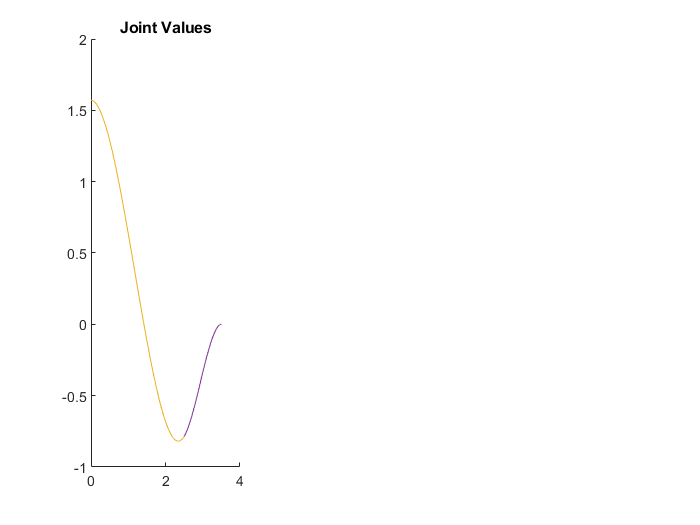

Index exceeds the number of array elements (3).

Error in spline_plot_norm (line 21)
        taut = (t - tvals(i)) / (tvals(i+1) - tvals(i));


spline_plot_norm(tvals, coeffs)